# mstle_phsdstrbtn analysis

Copyright © 2020 Yuichi Takeuchi

## initialization

clear; clc

## metainfo

ID = 'LTR1_82_83';
closed = 0; % 0 and 1 for open-loop and closed-loop control
metainfo = {
    'AP', 190403, 2, 1, [82 83], [7 7]; % [22 14] % prefix, date, expNo1, expNo2, LTR, specific ch
    'AP', 190404, 1, 1, [82 83], [7 7];
    'AP', 190405, 1, 1, [82 83], [7 7];
    };

## path

addpath(genpath('helper'))
addpath(genpath('lib'))

## Downsampling and channel reorganization

for i = 1:size(metainfo,1)
    ds_Takeuchi3dual_2A1D_20k_to_500(metainfo{i,1}, metainfo{i,2}, metainfo{i,3}, metainfo{i,4})
end

dat file preparations...
processing AP_190403_exp2_1.dat
resampling dat file...
resampling done
fileiof_writeInt16DatFile flag = 
extracting a digital channel...
Extracting 63 ch from AP_190403_exp2_1_DSampled.dat ...
Extracting channels...
1 of 6 chunks
2 of 6 chunks
3 of 6 chunks
4 of 6 chunks
5 of 6 chunks
6 of 6 chunks
Extraction done.
channel extraction done.
extracting analog input channels...
Extracting 61 ch from AP_190403_exp2_1_DSampled.dat ...
Extracting channels...
1 of 6 chunks
2 of 6 chunks
3 of 6 chunks
4 of 6 chunks
5 of 6 chunks
6 of 6 chunks
Extraction done.
Extracting 62 ch from AP_190403_exp2_1_DSampled.dat ...
Extracting channels...
1 of 6 chunks
2 of 6 chunks
3 of 6 chunks
4 of 6 chunks
5 of 6 chunks
6 of 6 chunks
Extraction done.
extracting analog channels done.
headstage inputs...
Extracting 2   1   3   5   6   4   8   7   9  11  12  10  14  13  15  17  16  18  20  21  19  23  22  24  26  25  27  29  30  28 ch from AP_190403_exp2_1_DSampled.dat ...
Extracting ch

flag = 1
processing done
Elapsed time is 757.391632 seconds.
dat file preparations...
processing AP_190404_exp1_1.dat
resampling dat file...
resampling done
fileiof_writeInt16DatFile flag = 
extracting a digital channel...
Extracting 63 ch from AP_190404_exp1_1_DSampled.dat ...
Extracting channels...
1 of 10 chunks
2 of 10 chunks
3 of 10 chunks
4 of 10 chunks
5 of 10 chunks
6 of 10 chunks
7 of 10 chunks
8 of 10 chunks
9 of 10 chunks
10 of 10 chunks
Extraction done.
channel extraction done.
extracting analog input channels...
Extracting 61 ch from AP_190404_exp1_1_DSampled.dat ...
Extracting channels...
1 of 10 chunks
2 of 10 chunks
3 of 10 chunks
4 of 10 chunks
5 of 10 chunks
6 of 10 chunks
7 of 10 chunks
8 of 10 chunks
9 of 10 chunks
10 of 10 chunks
Extraction done.
Extracting 62 ch from AP_190404_exp1_1_DSampled.dat ...
Extracting channels...
1 of 10 chunks
2 of 10 chunks
3 of 10 chunks
4 of 10 chunks
5 of 10 chunks
6 of 10 chunks
7 of 10 chunks
8 of 10 chunks
9 of 10 chunks
10 of 10

flag = 1
processing done
Elapsed time is 1254.047044 seconds.
dat file preparations...
processing AP_190405_exp1_1.dat
resampling dat file...
resampling done
fileiof_writeInt16DatFile flag = 
extracting a digital channel...
Extracting 63 ch from AP_190405_exp1_1_DSampled.dat ...
Extracting channels...
1 of 10 chunks
2 of 10 chunks
3 of 10 chunks
4 of 10 chunks
5 of 10 chunks
6 of 10 chunks
7 of 10 chunks
8 of 10 chunks
9 of 10 chunks
10 of 10 chunks
Extraction done.
channel extraction done.
extracting analog input channels...
Extracting 61 ch from AP_190405_exp1_1_DSampled.dat ...
Extracting channels...
1 of 10 chunks
2 of 10 chunks
3 of 10 chunks
4 of 10 chunks
5 of 10 chunks
6 of 10 chunks
7 of 10 chunks
8 of 10 chunks
9 of 10 chunks
10 of 10 chunks
Extraction done.
Extracting 62 ch from AP_190405_exp1_1_DSampled.dat ...
Extracting channels...
1 of 10 chunks
2 of 10 chunks
3 of 10 chunks
4 of 10 chunks
5 of 10 chunks
6 of 10 chunks
7 of 10 chunks
8 of 10 chunks
9 of 10 chunks
10 of 1

flag = 1
processing done
Elapsed time is 1471.902057 seconds.


clear i

## Get timestamps of seizure induction (digital channel bit 0)

% get timestamps of seizure induction, detections of rat 1, rat2 
RecInfo = cell(1, size(metainfo,1));
DataStruct = cell(1, size(metainfo,1));
for i = 1:size(metainfo,1)
    [tmpRecInfo] = getRecInfo(metainfo{i,1}, metainfo{i,2}, metainfo{i,3}, metainfo{i,4}, metainfo{i,5}, 500);
    [tmpDataStruct] = getDataStruct(tmpRecInfo);
    RecInfo{i} = tmpRecInfo;
    DataStruct{i}(1) = tmpDataStruct;
    DataStruct{i}(2) = tmpDataStruct; % duplication
end
save(['tmp/' ID '_' num2str(closed) '_RecInfo.mat' ], 'RecInfo')
save(['tmp/' ID '_' num2str(closed) '_DataStruct.mat'], 'DataStruct')
clear i tmpRecInfo tmpDataStruct

## Manual curation of timestamp

cidx = {
    1, 1, [], repmat([1 0],1,4); % record num of metainfo, rat No, rejection trial no, trues for trials to be analyzed
    1, 2, [7 8], repmat([0 1],1,3);
    2, 1, [1 2], repmat([1 0],1,3);
    2, 2, [], repmat([0 1],1,4);
    };
load(['tmp/' ID '_' num2str(closed) '_DataStruct.mat'], 'DataStruct')
for i = 1:size(cidx, 1)
    DataStruct{1,cidx{i,1}}(cidx{i,2}).Timestamp{1, 1}(cidx{i,3},:) = [];
    DataStruct{1,cidx{i,1}}(cidx{i,2}).TimestampMin(cidx{i,3},:) = [];
    DataStruct{1,cidx{i,1}}(cidx{i,2}).idxslct = cidx{i,4};
end
save(['tmp/' ID '_' num2str(closed) '_DataStruct_curated.mat'], 'DataStruct')
clear cidx i

## Trial file extraction, Filtering, define detection timestamps

for i = 1:size(metainfo,1)
    [flag] = cut_postInductionTime_Takeuchi3_dual(RecInfo{i}, DataStruct{i});
end
clear i flag

## Circular phase analysis

polarhist = 1;
tic
for i = 1:size(metainfo,1)  % for by dat file
    [Tb] = tableResultantVectorStacks(closed, RecInfo{i}, DataStruct{i}, metainfo{i,6}, polarhist);
    if i ~= 1
        Tb = [Tb;Tb];
    end
end
toc
clear i polarhist

## csv and compass file outputs

start analysis...
AP_190130_exp1_1_LFP500_1.dat
RatNo: 1
TrialNo: 1
TrialNo: 2
TrialNo: 3
TrialNo: 4
AP_190130_exp1_1_LFP500_2.dat
RatNo: 2
TrialNo: 1
TrialNo: 2
TrialNo: 3
done
Elapsed time is 0.204509 seconds.
start analysis...
AP_190130_exp1_1
RatNo: 1
TrialNo: 1
TrialNo: 2
TrialNo: 3
TrialNo: 4
AP_190130_exp1_1
RatNo: 2
TrialNo: 1
TrialNo: 2
TrialNo: 3
done
Elapsed time is 0.062015 seconds.
start analysis...
AP_190204_exp1_1_LFP500_1.dat
RatNo: 1
TrialNo: 1
TrialNo: 2
TrialNo: 3
AP_190204_exp1_1_LFP500_2.dat
RatNo: 2
TrialNo: 1
TrialNo: 2
TrialNo: 3
TrialNo: 4
done
Elapsed time is 0.169358 seconds.
start analysis...
AP_190204_exp1_1
RatNo: 1
TrialNo: 1
TrialNo: 2
TrialNo: 3
AP_190204_exp1_1
RatNo: 2
TrialNo: 1
TrialNo: 2
TrialNo: 3
TrialNo: 4
done
Elapsed time is 0.051423 seconds.


RatNo: 1


fldrInfoadc = 4×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 4.558254e-01


mu = 2.134236e+00


rayleigh test


   1



MI = 2.5806

     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 3.696787e-01


mu = 2.016462e+00


rayleigh test


   1



MI = 3.0087

     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 5.961706e-02


mu = 1.444053e+00


rayleigh test


   0



MI = 0.7669

     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 2.260706e-01


mu = -2.544287e-01


rayleigh test


   1



MI = 1.3625

RatNo: 2


fldrInfoadc = 3×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 8.305627e-01


mu = 1.874417e+00


rayleigh test


   1



MI = 4.8324

     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 8.052149e-01


mu = 1.833552e+00


rayleigh test


   1



MI = 3.9551

     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 8.608087e-01


mu = 1.966198e+00


rayleigh test


   1



MI = 6.4483

RatNo: 1


fldrInfoadc = 3×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 3.384604e-01


mu = 1.939047e+00


rayleigh test


   1



MI = 1.4000

     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 1.614611e-01


mu = -3.982204e-01


rayleigh test


   1



MI = 1.1522

     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 3.312271e-01


mu = 1.925601e+00


rayleigh test


   1



MI = 1.9647

RatNo: 2


fldrInfoadc = 4×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 8.513509e-01


mu = 2.115892e+00


rayleigh test


   1



MI = 6.2198

     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 7.302239e-01


mu = 1.770558e+00


rayleigh test


   1



MI = 3.9749

     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 8.814733e-01


mu = 2.102288e+00


rayleigh test


   1



MI = 8.7612

     1



Low-pass filtering...
Low-pass filtering done.


High-pass filtering...
High-pass filtering done.


r = 9.784304e-01


mu = 2.126461e+00


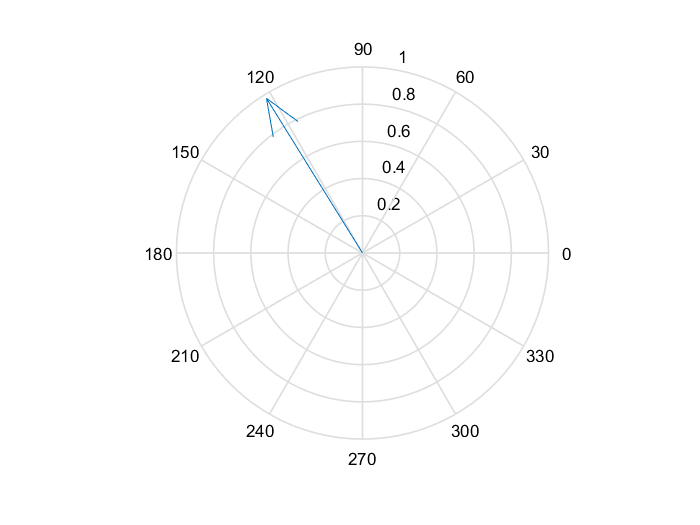

rayleigh test


   1



MI = 7.5610

writetable(Tb, ['../results/' ID '_closed_resultantVec.csv'])
printCompassPDFPNG(Tb, ID)
disp('done')